# **IO751 & IO752 - Synchronous PROFINET**

The IO751 and IO752 are PROFINET I/O modules to connect real-time target machines to industrial equipment. The IO751 is a PROFINET Controller module that is used to communicate with field-level devices such as motor controllers and sensors. The IO752 is a PROFINET Device module that is used to communicate with devices on the control and process level such as programmable logic controllers. The modules handle the complete data exchange between the real-time application and the connected devices. The data exchange is processed via a dual-port memory. Each module acts as one PROFINET station exclusively. The two Ethernet connectors enable easy network integration.

PROFINET communication typically takes place between one PROFINET Controller and multiple PROFINET Devices. In this example, one controller (IO751) communicates with one device (IO752) installed in the same target machine. Both the controller and the device are configured for synchronous communication at 1 kHz.

The IO751 requires a configuration file (included with this example). The file is created with SYCON.net, a software tool from Hilscher. 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO751 and one IO752 installed

- CAT5 Ethernet cable or newer

The IO751 requires a configuration file. This file comes with the example model and does not have to be created. However, the SYCON.net project is also included in the example and can be used to recreate the configuration file. The module help documentation and the SYCON documentation explain how to use SYCON.net, which is free of charge.

### Pin Mapping/Connection Diagram/Test Setup

PROFINET is an Ethernet-based protocol. Use a CAT5 cable or newer to connect the IO751 with the IO752. Both modules have two connectors. It does not matter which one you use.

The configuration file (*.nxd) for the IO751 is automatically packed into the real-time application by the build process and unpacked during the initialization of the real-time application on the target.

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO751_IO752_PROFINETSynchronous';
open_system(modelName);

### Model Description

The model sets up the communication for both the IO751 and IO752. When starting the model, the IO751 Setup block loads the corresponding configuration file onto the I/O module. The Receive and Send blocks are used to exchange data.

The IO751 is configured to send a counter signal of type uint32 (4 bytes) to the IO752. The IO752 simply sends the signal back. The IO751 receives the counter and calculates a signal delay from both signals. As the communication is synchronized, a constant delay of 2 cycles is expected.

The Send and Receive blocks do not run in polling mode. Instead, for the purpose of synchronization, the blocks reside in function-call subsystems triggered by Interrupt Setup blocks.  Both I/O modules throw PCI interrupts according to the base clock of the sync master (the IO751). The subsystems containing the Send and Receive blocks are triggered by these interrupts. This guarantees that incoming values are not processed twice and do not get lost.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Set the stop time
tg.setStopTime(20);     % seconds

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(3,1);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('ToDevice');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('FromDevice');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('ToController');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('FromController');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('Num_Interrupts_Controller');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('Num_Interrupts_Device');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('MaxDelay');
plotOnSubPlot(s,3,1,true);

Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,20,-100,17000]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,20,-100,17000]);
Simulink.sdi.setSubplotLimits(3,1,'AllRange',[0,20,-1,3]);


### Check the Results

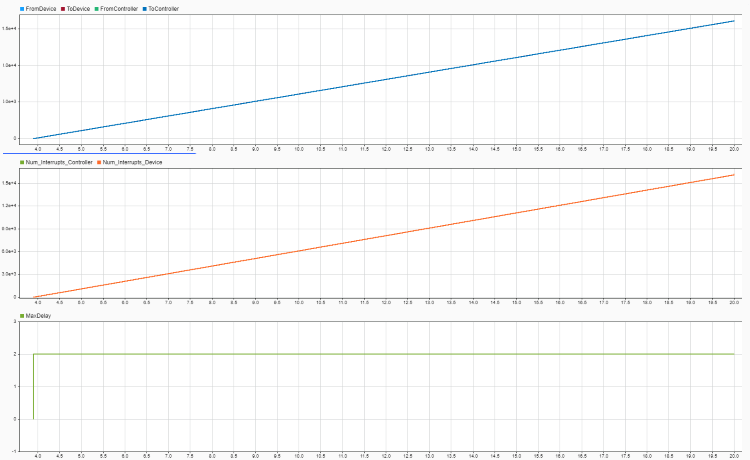

## Additional References

- [IO751 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io751)

- [IO752 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io752)